%http://correll.cs.colorado.edu/?p=1869
clear all
clc
W = 224 %mm

W = 224

L = 212 %mm

L = 212


global vs ws time
%%%%%%%%%%%%%%%%%%%%%%%%Squares%%%%%%%%%%%%%%%%%%%%%%%%
    vs = [];
    ws = [];
    time = [];

    allTimeActualx = [];
    allTimeDesiredVec = [];
    allTimeErrorVec = [];
    allT = [];
    %First Line
    Ti = 0;
    Tf=4; % Total Time
    actualInit=[1, 0, 0]; % Initial Condition where the robot starts.
    xdes_vecInit=[1, 0.5, 0]; %initial Desired configuration
    
    [actualx, xdes_vec, error_vec, tSteps] = followStraightLine(actualInit, xdes_vecInit, Ti, Tf, 1, 0);
    
    allTimeActualx = [allTimeActualx; actualx;];
    allTimeDesiredVec = [ allTimeDesiredVec; xdes_vec];
    allTimeErrorVec = [ allTimeErrorVec; error_vec];
    allT = [allT; tSteps];
    
    %Second Line
    Ti = Tf;
    Tf=8; % Total Time
    
    
    actualInit=allTimeActualx(end, :); % Initial Condition where the robot starts.
    xdes_vecInit=[5, 0.5, pi/2]; %initial Desired configuration
    
    [actualx, xdes_vec, error_vec, tSteps] = followStraightLine(actualInit, xdes_vecInit, Ti, Tf, 0, 1);
    
    allTimeActualx = [allTimeActualx; actualx;];
    allTimeDesiredVec = [ allTimeDesiredVec; xdes_vec];
    allTimeErrorVec = [ allTimeErrorVec; error_vec];
    allT = [allT; tSteps];
    
    %Third Line
    Ti = Tf;
    Tf=12; % Total Time

    actualInit=allTimeActualx(end, :); % Initial Condition where the robot starts.
    xdes_vecInit=[5, 4.5, pi]; %initial Desired configuration
    
    [actualx, xdes_vec, error_vec, tSteps] = followStraightLine(actualInit, xdes_vecInit, Ti, Tf, -1, 0);
    
    allTimeActualx = [allTimeActualx; actualx;];
    allTimeDesiredVec = [ allTimeDesiredVec; xdes_vec];
    allTimeErrorVec = [ allTimeErrorVec; error_vec];
    allT = [allT; tSteps];
    
    %Fourth Line
    Ti = Tf;
    Tf=16; % Total Time
    actualInit=allTimeActualx(end, :); % Initial Condition where the robot starts.
    xdes_vecInit=[1, 4.5, pi*3/2]; %initial Desired configuration
    
    [actualx, xdes_vec, error_vec, tSteps] = followStraightLine(actualInit, xdes_vecInit, Ti, Tf, 0, -1);
    
    allTimeActualx = [allTimeActualx; actualx;];

allTimeActualx =     1.0000         0         0
    1.0058         0    0.0272
    1.0117    0.0002    0.0551
    1.0179    0.0005    0.0846
    1.0245    0.0011    0.1158
    1.0314    0.0019    0.1486
    1.0386    0.0029    0.1830
    1.0461    0.0043    0.2190
    1.0539    0.0061    0.2541
    1.0619    0.0081    0.2869


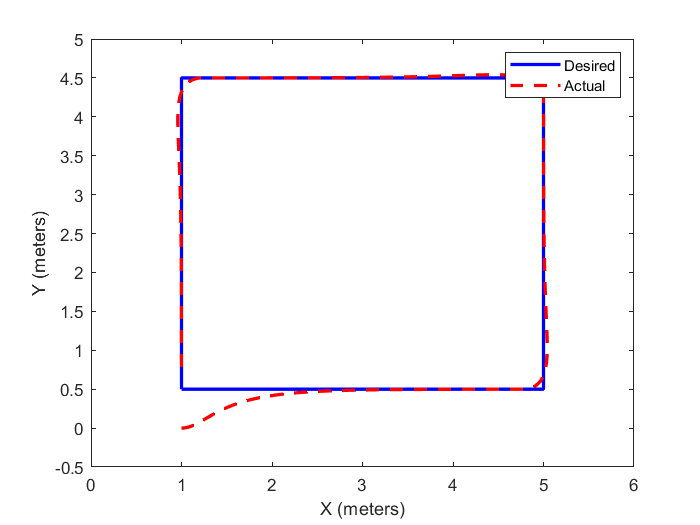

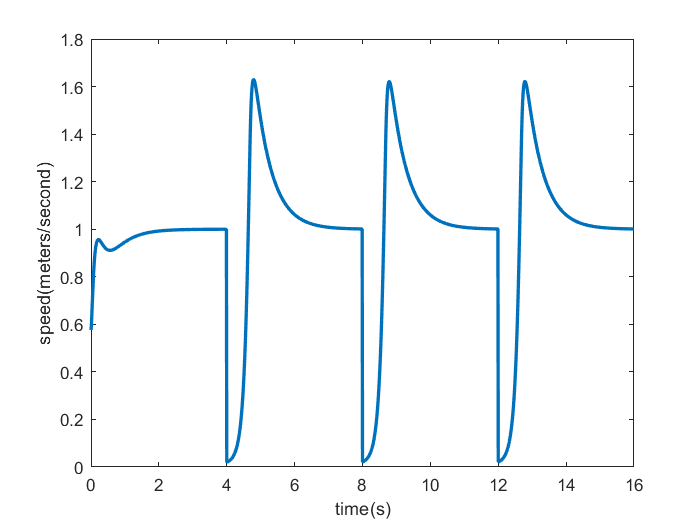

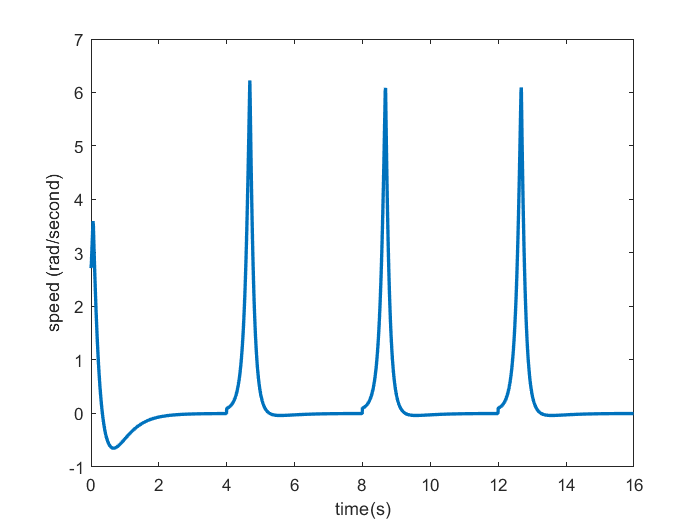

    allTimeDesiredVec = [ allTimeDesiredVec; xdes_vec];
    allTimeErrorVec = [ allTimeErrorVec; error_vec];
    allT = [allT; tSteps];
    

    plotStuff(allTimeActualx)

function [dx ] = errordynamics(t,x,y1Dotd, y2Dotd, y1d, y2d)
    global vs ws time
    carLength = .212;
    dr=.7; %zeta in textbook
    wd=0; 
    vd=1; 
    nf=1; %a in textbook
    b = 0.212; 
    k1=2;
    k2=2;
    dx=zeros(1,3);
    y1 = x(1)+b*cos(x(3));
    y2 = x(2)+b*sin(x(3));
    u1 = y1Dotd+k1*(y1d-y1);
    u2 = y2Dotd+k2*(y2d-y2);
    thetaDot = (u2*cos(x(3))-(u1*sin(x(3))))/b;
    f = [cos(x(3)), sin(x(3));-sin(x(3))/b, cos(x(3))/b]*[u1;u2];
    v = f(1);
    w = f(2);
    [v, w] = limiter(v, w, carLength, 3, pi/4);
    dx(1) = cos(x(3))*v;
    dx(2) = sin(x(3))*v;
    dx(3) = w;
    vs = [vs v];
    ws = [ws w];
    time = [time t];
end

function [actualx, xdes_vec, error_vec, tSteps] = followStraightLine(initial, desired, ti, tf, vdX, vdY)
    dt = 0.01;
    x = initial;%desired-initial;
    tSteps = ti:dt:tf;
    error_vec = x;
    xdes_vec = desired;
    temp = size(tSteps);
    for i=1:temp(2)-1
        % calculating the desired trajectory
        xdes= desired(1)+vdX*(tSteps(i)-ti);
        ydes= desired(2)+vdY*(tSteps(i)-ti);
        if(vdX==1)
           tdes=0 ;
        end
        if(vdX==-1)
           tdes=pi ;
        end
        if(vdY==1)
           tdes=pi/2 ;
        end
        if(vdY==-1)
           tdes=pi*3/2 ;
        end
        xdes_vec = [xdes_vec; [xdes, ydes, tdes]];
    end
    for i=1:temp(2)-1
         t = tSteps(i);
         [dx] = errordynamics(t,x, vdX, vdY, xdes_vec(i, 1), xdes_vec(i, 2)); % ode to solve edot=A*e
         x = x+dx*dt;
         error_vec = [error_vec; [x(1) x(2) x(3)]];
    end
    actualx = error_vec;

end
   
function [] = plotStuff(actualx)
    global vs ws time
    figure
    
    plot([1 5 5 1 1], [0.5 0.5 4.5 4.5 0.5],'b-', 'LineWidth', 2);
        xlim([0 6])
        ylim([-0.5 5])
    hold on 
    plot(actualx(:,1), actualx(:,2),'r--', 'LineWidth', 2);
    xlabel('X (meters)');
    ylabel('Y (meters)');
    legend('Desired', 'Actual');
  
    figure
    plot(time, vs,'LineWidth', 2);
    xlim([0,16])
    ylabel('speed(meters/second)');
    xlabel('time(s)');
    
     figure
    plot(time, ws,'LineWidth', 2);
    xlim([0,16])
    ylabel('speed (rad/second)');
    xlabel('time(s)');
    
end

function [v, w] = limiter(v, w, carLength, vLim, maxSteerAngle)
    %limit Velocity
    if v>vLim
        v = vLim;
    elseif v < -vLim
        v = -vLim;
    end
    %Calc steering angle
    psi = atan(w*carLength/v);
    if psi > maxSteerAngle
        psi = maxSteerAngle;
    elseif psi < -maxSteerAngle
        psi = -maxSteerAngle;
    end
    w = tan(psi)/carLength*v;
end
